# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 5.6.1 Map Drift

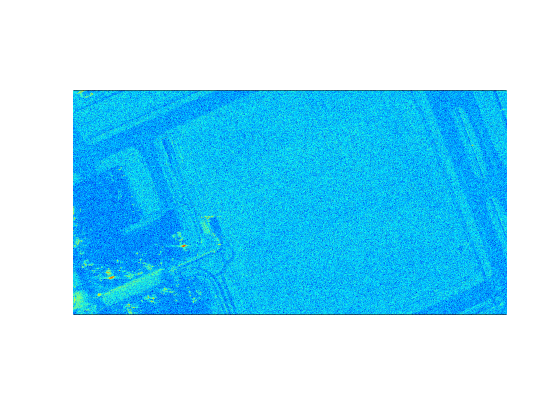

[file,path] = uigetfile('*.h5');
filename = fullfile(path,file);

% Form the complex data
s_i = h5read(filename, '/s_i');
s_q = h5read(filename, '/s_q');
s = double(s_i) + 1j * double(s_q);

clear s_i s_q

% Set the dynamic range for the image
dynamic_range = 65;

% Data size
[nx, ny] = size(s);
ratio = ny/nx;

% Pixel offset from image center
offset_x = 0;
offset_y = 0;

% New center
xc = round(nx/2) - offset_x;
yc = round(ny/2) - offset_y;

% Specify a span / or fixed aspect
xs = 1000;
ys = 2000;
% ys = round(ratio * xs);

% For full image
% xs = nx/2-1;
% ys = ny/2-1;

% Calculate the image indices
index_x = xc-xs:xc+xs;
index_y = yc-ys:yc+ys;

% For specifying a particular location and size in the image
% index_x = (1:3000) + 1000;
% index_y = (1:8000) + 1000;

xs = round( (index_x(end) - index_x(1)) / 2);
ys = round( (index_y(end) - index_y(1)) / 2);

% Extract the desired portion of the image
s = s(index_x, index_y);  [nx, ny] = size(s);

% Calculate the quadratic phase error
t = linspace(-10, 10, nx);
phi = t.^2;

% Calculate the phase error term
phase_term = exp(1j * phi') * ones(1, ny);
sf = fftshift(fft(s, [], 1), 1);
s_e = ifft(phase_term .* sf);

% Make the two subaperture images
t1 = linspace(-10, 0, nx); phi1 = t1.^2; phase_term1 = exp(1j * phi1') * ones(1, ny);
t2 = linspace(0, 10, nx);  phi2 = t2.^2; phase_term2 = exp(1j * phi2') * ones(1, ny);

image1 = ifft(phase_term1 .* sf); image1 = movsum(image1, 32, 2)/32;
image2 = ifft(phase_term2 .* sf); image2 = movsum(image2, 32, 2)/32;

% Calculate the cross-power spectrum of the original and transformed images
image_original_spectrum = fft(image1);
image_transformed_spectrum = fft(image2);

translation = abs(ifft((image_original_spectrum .* conj(image_transformed_spectrum)) ./...
    (abs(image_original_spectrum) .* abs(image_transformed_spectrum))));

% Find the peak error location
[C, I] = max(translation(:));
[tx, ~] = ind2sub(size(translation), I);
phase_error_peak = tx * pi;

% Calculate the phase correction
tc = linspace(-1, 1, nx);
phi_correction = phase_error_peak * tc.^2;

% Calculate the phase correction term
phase_term = exp(-1j * phi_correction') * ones(1, ny);
sef = (fft(s_e, [], 1));
s_c = ifft(phase_term .* sef);

% Original image
figure;
pcolor(flipud(db(s)')); shading flat;
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])

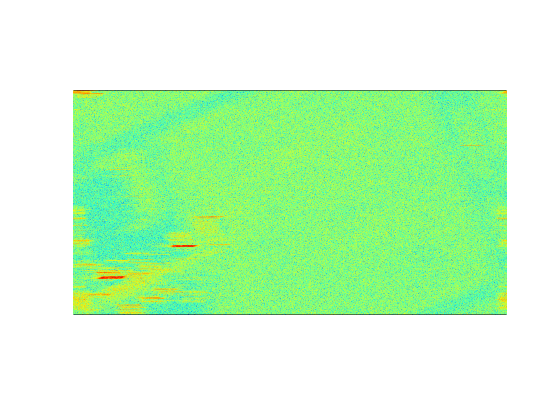


% Corrupted image
figure;
pcolor(flipud(db(s_e)')); shading flat;
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])

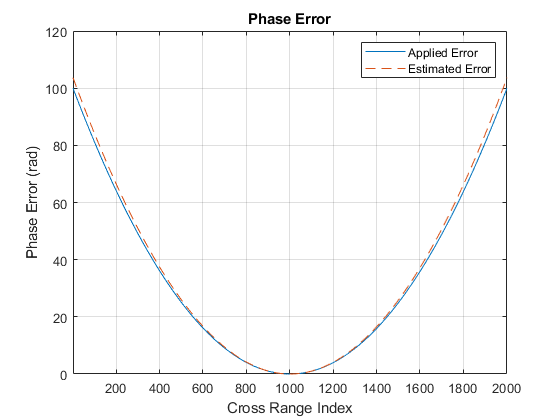


% Compare phase error correction
figure;
plot(phi); 
hold on; 
plot(phi_correction, '--');
title('Phase Error')
ylabel('Phase Error (rad)')
xlabel('Cross Range Index')
legend('Applied Error', 'Estimated Error');
xlim([1, length(phi)])
grid on

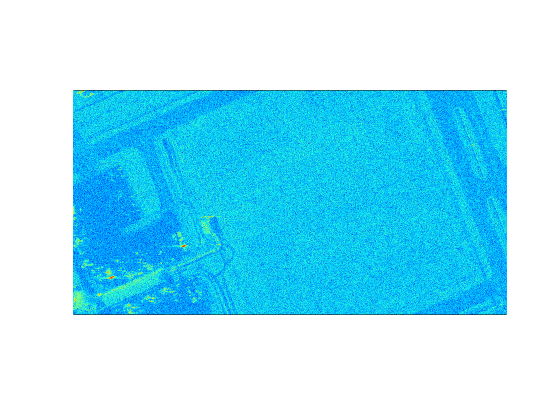


% Corrected image
figure;
pcolor(flipud(db(s_c)')); shading flat;
set(gca,'XTick',[], 'YTick', [])
colormap jet
caxis([-abs(dynamic_range), 0]);
axis square
pbaspect([ratio * xs / ys 1 1])